syms t
assume(t, ["real", "positive"])

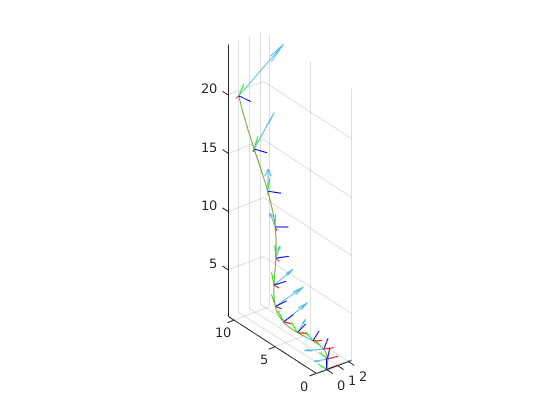

TF frames displayed: 13

% Axis of rotation as a function of time
alpha = [
    1;
    1;
    0;
];
alpha = alpha / norm(alpha);
% Angle of rotation as a function of time
theta = 0.2*t;

% Construct the quaternion using axis-angle
q_t = [
    cos(theta/2);
    sin(theta/2)*alpha;
];

r_t = [
    sin(t);
    t;
    exp(0.3*t);
];

tab_sim = generate_trajectory(tspan, r_t, q_t);

viz_trajectory(tab_sim)